close all;
clear;

## Loading system parameters

parameters_maggy_V2;
% Define the point to linearize around
paramsFast = params;
correctionFactorFast = computeSolenoidRadiusCorrectionFactor(params,'fast');
paramsFast.solenoids.r = correctionFactorFast*paramsFast.solenoids.r;
[zEq, zEqInv, dzEq, dzEqInv] = computeSystemEquilibria(paramsFast,'fast');
xLp = [0,0,zEq(1),zeros(1,9)]'; % Linearizing around the equilibria
uLp = zeros(length(params.solenoids.r),1);

% Define the model to be used in linearization
modelName = 'fast';

% Setting up system equations with speficied model and parameters for
% simpler representation
f = @(x,u) maglevSystemDynamics(x,u,paramsFast,modelName);
h = @(x,u) maglevSystemMeasurements(x,u,paramsFast,modelName);

fprintf('Equilibria: ')

Equilibria: 

xLp

xLp =          0
         0
    0.0365
         0
         0
         0
         0
         0
         0
         0


## Linearization

Linearization is an important tool for analyzing stability and designing linear controllers for nonlinear systems. Here, we see how to linearize the maglev system.

% Define the point to linearize around
xLp = [0,0,zEq(1),zeros(1,9)]'; % Linearizing around the equilibria
uLp = zeros(length(params.solenoids.r),1);

% Linearization
delta = 1e-6; % Step-size used in numerical linearization
[A,B,C,D] = finiteDifferenceLinearization(f,h,xLp,uLp,delta);

fprintf('Size of A: %.f, %.f\n', size(A))

Size of A: 12, 12


fprintf('Size of B: %.f, %.f\n', size(B))

Size of B: 12, 4


fprintf('Size of C: %.f, %.f\n', size(C))

Size of C: 9, 12


fprintf('Size of D: %.f, %.f\n', size(D))

Size of D: 9, 4


## LQR control

Using the linearized model from above, we can define a simple LQR controller in order to stabilize the system at the equilibrium.

### Designing LQR controller

The rotation around the center axis of the levitating magnet is uncontrollable. Thus, the rotation of the linear model is uncontrollable around the z-axis (since the axis of the magnet is parallel with it in the equilibrium). Luckily, we do not need to worry about this axis when controlling the system because it does not affect any of the other states in the linear model, so we may just remove them from the linear model when designing our controller:

% Defining reduced order system
I = [1:5,7:11];
Ared = A(I,I);
Bred = B(I,:);
Cred = C(:,I);
Dred = D(:,:);

% Cost matrices
Q = diag([1e6,1e6,1e2, 1e1,1e1, 1e2,1e2,1e2, 1e2,1e2]);
R = 1e-0*eye(length(params.solenoids.r));

% Computing LQR estimate
Kred = round(lqr(Ared,Bred,Q,R),3); % Rounding can sometimes be dangerous!

% increasing order of our controller for controlling the real system
K = [Kred(:,1:5), zeros(4,1), Kred(:,6:end), zeros(4,1)];


## **Load Policy Parameters or select Random Policy**

%f = @(x,u) maglevSystemDynamics_contrained_horizontal(x,u,paramsFast,modelName);

exploration = 0;
K_end = -1;

U_MAX = 50;
dt = 0.02

dt = 0.0200

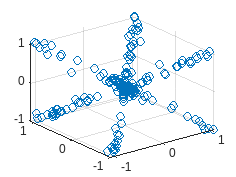

if exploration == 0
    policy_centers = table2array(readtable('policy/policy_centers.csv'));
    policy_f_linear_weight = table2array(readtable('policy/policy_f_linear.weight.csv'));
    W=policy_f_linear_weight;
    policy_log_lengthscales = table2array(readtable('policy/policy_log_lengthscales.csv'));
    policy_lengthscales = exp(policy_log_lengthscales');
    
    phi = @(x) [x(1:3)' x(7:12)' cos(x(4:6))' sin(x(4:6))']';
    figure
    scatter3(policy_centers(:,1), policy_centers(:,2), policy_centers(:,3))
end

k_rep = 0;

while K_end < 10
    if exploration > 0
        tf = 3.0
        %policy = @(x, t) - K*(x-xLp)-uLp;
        policy = @(x, t) 1 * t * sin(2*5*pi*t*ones(4,1)) - K*(x-xLp)-uLp;
        x0 = xLp + [0.004 -0.001 0.0 0 0 0 zeros(1, 6)]';
    else
        tf = .4

        u_max = U_MAX / (2^k_rep)
        
        %policy = @(x, t) - K*(x-xLp)-uLp + u_max * tanh( W * exp(-sum( ((policy_centers-phi(x)')./policy_lengthscales').^2, 2)) / u_max);
        policy = @(x, t) u_max * tanh( W * exp(-sum( ((policy_centers-phi(x)')./policy_lengthscales').^2, 2)) / u_max);
        x0 = xLp; % + [randn(1,3)*0.0 zeros(1,9)]'
    
        
    end
    % Simulation
    tic
    % Initialize variables
    % Initial condition
    
    % Pre-allocate arrays to store results
    num_steps = round(tf / dt);    u_result = zeros(num_steps, 4);
    tSpan = linspace(0,tf,num_steps);
    
%     x_result = zeros(num_steps, 12);
%     u_result = zeros(num_steps, 4);
%     x_current = x0;
%     t_current = 0.0;
%     tic
%     for i = 1:num_steps
%         x_result(i, :) = x_current;
%         u = policy(x_current', t_current);
%         u_result(i, :) = u;
%         [t_out, x_out] = ode15s(@(t, x) f(x, u), [t_current t_current + dt], x_current);
%         t_current = t_out(end);
%         x_current = x_out(end, :) + + randn(1,12)*0.001; % measurement noise
%     end
    [t,x_result] = ode15s(@(t,x) f(x,policy(x,t)), tSpan, x0);
    
    
    for i=1:num_steps
        if x_result(i,3) < 0 || any(x_result(i,4:6)) > pi/3   % end simulation condition [To be optimized]
            K_end = i-2
            break
        end
        u_result(i,:) = policy(x_result(i,:)', tSpan(i));
        x_result(i,:) = x_result(i,:) + randn(1,12)*0.002;
    end
    
    if K_end > 0
        u_result = u_result(1:K_end, :);
        x_result = x_result(1:K_end, :);
        tSpan = tSpan(1:K_end);
    else
        K_end = length(x_result(:,1))
    end
    
    
    fprintf('simulation time: %.2fs\n', toc)
    k_rep = k_rep + 1 ;
end

tf = 0.4000

u_max = 50

K_end = 6

simulation time: 1.80s


tf = 0.4000

u_max = 25

K_end = 6

simulation time: 1.77s


tf = 0.4000

u_max = 12.5000

K_end = 6

simulation time: 2.14s


tf = 0.4000

u_max = 6.2500

K_end = 7

simulation time: 4.42s


tf = 0.4000

u_max = 3.1250

K_end = 8

simulation time: 3.40s


tf = 0.4000

u_max = 1.5625

simulation time: 0.45s


tf = 0.4000

u_max = 0.7813

simulation time: 0.04s


tf = 0.4000

u_max = 0.3906

simulation time: 0.04s


tf = 0.4000

u_max = 0.1953

simulation time: 0.03s


tf = 0.4000

u_max = 0.0977

simulation time: 0.05s


tf = 0.4000

u_max = 0.0488

simulation time: 0.03s


tf = 0.4000

u_max = 0.0244

simulation time: 0.03s


tf = 0.4000

u_max = 0.0122

simulation time: 0.04s


tf = 0.4000

u_max = 0.0061

simulation time: 0.03s


tf = 0.4000

u_max = 0.0031

simulation time: 0.03s


tf = 0.4000

u_max = 0.0015

simulation time: 0.03s


tf = 0.4000

u_max = 7.6294e-04

simulation time: 0.03s


tf = 0.4000

u_max = 3.8147e-04

simulation time: 0.02s


tf = 0.4000

u_max = 1.9073e-04

simulation time: 0.02s


tf = 0.4000

u_max = 9.5367e-05

simulation time: 0.01s


tf = 0.4000

u_max = 4.7684e-05

simulation time: 0.01s


tf = 0.4000

u_max = 2.3842e-05

simulation time: 0.01s


tf = 0.4000

u_max = 1.1921e-05

simulation time: 0.02s


tf = 0.4000

u_max = 5.9605e-06

simulation time: 0.02s


tf = 0.4000

u_max = 2.9802e-06

simulation time: 0.02s


tf = 0.4000

u_max = 1.4901e-06

simulation time: 0.02s


tf = 0.4000

u_max = 7.4506e-07

simulation time: 0.02s


tf = 0.4000

u_max = 3.7253e-07

simulation time: 0.02s


tf = 0.4000

u_max = 1.8626e-07

simulation time: 0.01s


tf = 0.4000

u_max = 9.3132e-08

simulation time: 0.02s


tf = 0.4000

u_max = 4.6566e-08

simulation time: 0.01s


tf = 0.4000

u_max = 2.3283e-08

simulation time: 0.01s


tf = 0.4000

u_max = 1.1642e-08

simulation time: 0.01s


tf = 0.4000

u_max = 5.8208e-09

simulation time: 0.02s


tf = 0.4000

u_max = 2.9104e-09

simulation time: 0.02s


tf = 0.4000

u_max = 1.4552e-09

simulation time: 0.02s


tf = 0.4000

u_max = 7.2760e-10

simulation time: 0.02s


tf = 0.4000

u_max = 3.6380e-10

simulation time: 0.02s


tf = 0.4000

u_max = 1.8190e-10

simulation time: 0.02s


tf = 0.4000

u_max = 9.0949e-11

simulation time: 0.02s


tf = 0.4000

u_max = 4.5475e-11

simulation time: 0.02s


tf = 0.4000

u_max = 2.2737e-11

simulation time: 0.03s


tf = 0.4000

u_max = 1.1369e-11

simulation time: 0.02s


tf = 0.4000

u_max = 5.6843e-12

simulation time: 0.02s


tf = 0.4000

u_max = 2.8422e-12

simulation time: 0.02s


tf = 0.4000

u_max = 1.4211e-12

simulation time: 0.02s


tf = 0.4000

u_max = 7.1054e-13

simulation time: 0.01s


tf = 0.4000

u_max = 3.5527e-13

simulation time: 0.01s


tf = 0.4000

u_max = 1.7764e-13

simulation time: 0.02s


tf = 0.4000

u_max = 8.8818e-14

simulation time: 0.01s


tf = 0.4000

u_max = 4.4409e-14

simulation time: 0.02s


tf = 0.4000

u_max = 2.2204e-14

simulation time: 0.02s


tf = 0.4000

u_max = 1.1102e-14

simulation time: 0.02s


tf = 0.4000

u_max = 5.5511e-15

simulation time: 0.02s


tf = 0.4000

u_max = 2.7756e-15

simulation time: 0.02s


tf = 0.4000

u_max = 1.3878e-15

simulation time: 0.02s


tf = 0.4000

u_max = 6.9389e-16

simulation time: 0.02s


tf = 0.4000

u_max = 3.4694e-16

simulation time: 0.01s


tf = 0.4000

u_max = 1.7347e-16

simulation time: 0.01s


tf = 0.4000

u_max = 8.6736e-17

simulation time: 0.01s


tf = 0.4000

u_max = 4.3368e-17

simulation time: 0.01s


tf = 0.4000

u_max = 2.1684e-17

simulation time: 0.01s


tf = 0.4000

u_max = 1.0842e-17

simulation time: 0.01s


tf = 0.4000

u_max = 5.4210e-18

simulation time: 0.01s


tf = 0.4000

u_max = 2.7105e-18

simulation time: 0.01s


tf = 0.4000

u_max = 1.3553e-18

simulation time: 0.01s


tf = 0.4000

u_max = 6.7763e-19

simulation time: 0.01s


tf = 0.4000

u_max = 3.3881e-19

simulation time: 0.01s


tf = 0.4000

u_max = 1.6941e-19

simulation time: 0.01s


tf = 0.4000

u_max = 8.4703e-20

simulation time: 0.01s


tf = 0.4000

u_max = 4.2352e-20

simulation time: 0.01s


tf = 0.4000

u_max = 2.1176e-20

simulation time: 0.01s


tf = 0.4000

u_max = 1.0588e-20

simulation time: 0.01s


tf = 0.4000

u_max = 5.2940e-21

simulation time: 0.01s


tf = 0.4000

u_max = 2.6470e-21

simulation time: 0.01s


tf = 0.4000

u_max = 1.3235e-21

simulation time: 0.01s


tf = 0.4000

u_max = 6.6174e-22

simulation time: 0.01s


tf = 0.4000

u_max = 3.3087e-22

simulation time: 0.01s


tf = 0.4000

u_max = 1.6544e-22

simulation time: 0.01s


tf = 0.4000

u_max = 8.2718e-23

simulation time: 0.01s


tf = 0.4000

u_max = 4.1359e-23

simulation time: 0.01s


tf = 0.4000

u_max = 2.0680e-23

simulation time: 0.01s


tf = 0.4000

u_max = 1.0340e-23

simulation time: 0.01s


tf = 0.4000

u_max = 5.1699e-24

simulation time: 0.01s


tf = 0.4000

u_max = 2.5849e-24

simulation time: 0.01s


tf = 0.4000

u_max = 1.2925e-24

simulation time: 0.01s


tf = 0.4000

u_max = 6.4623e-25

simulation time: 0.01s


tf = 0.4000

u_max = 3.2312e-25

simulation time: 0.01s


tf = 0.4000

u_max = 1.6156e-25

simulation time: 0.01s


tf = 0.4000

u_max = 8.0779e-26

simulation time: 0.01s


tf = 0.4000

u_max = 4.0390e-26

simulation time: 0.01s


tf = 0.4000

u_max = 2.0195e-26

simulation time: 0.01s


tf = 0.4000

u_max = 1.0097e-26

simulation time: 0.01s


tf = 0.4000

u_max = 5.0487e-27

simulation time: 0.01s


tf = 0.4000

u_max = 2.5244e-27

simulation time: 0.01s


tf = 0.4000

u_max = 1.2622e-27

simulation time: 0.01s


tf = 0.4000

u_max = 6.3109e-28

simulation time: 0.01s


tf = 0.4000

u_max = 3.1554e-28

simulation time: 0.01s


tf = 0.4000

u_max = 1.5777e-28

simulation time: 0.01s


tf = 0.4000

u_max = 7.8886e-29

simulation time: 0.01s


tf = 0.4000

u_max = 3.9443e-29

simulation time: 0.01s


tf = 0.4000

u_max = 1.9722e-29

simulation time: 0.02s


tf = 0.4000

u_max = 9.8608e-30

simulation time: 0.01s


tf = 0.4000

u_max = 4.9304e-30

simulation time: 0.01s


tf = 0.4000

u_max = 2.4652e-30

simulation time: 0.01s


tf = 0.4000

u_max = 1.2326e-30

simulation time: 0.01s


tf = 0.4000

u_max = 6.1630e-31

simulation time: 0.01s


tf = 0.4000

u_max = 3.0815e-31

simulation time: 0.01s


tf = 0.4000

u_max = 1.5407e-31

simulation time: 0.01s


tf = 0.4000

u_max = 7.7037e-32

simulation time: 0.01s


tf = 0.4000

u_max = 3.8519e-32

simulation time: 0.01s


tf = 0.4000

u_max = 1.9259e-32

simulation time: 0.01s


tf = 0.4000

u_max = 9.6296e-33

simulation time: 0.01s


tf = 0.4000

u_max = 4.8148e-33

simulation time: 0.01s


tf = 0.4000

u_max = 2.4074e-33

simulation time: 0.01s


tf = 0.4000

u_max = 1.2037e-33

simulation time: 0.01s


tf = 0.4000

u_max = 6.0185e-34

simulation time: 0.01s


tf = 0.4000

u_max = 3.0093e-34

simulation time: 0.01s


tf = 0.4000

u_max = 1.5046e-34

simulation time: 0.01s


tf = 0.4000

u_max = 7.5232e-35

simulation time: 0.01s


tf = 0.4000

u_max = 3.7616e-35

simulation time: 0.01s


tf = 0.4000

u_max = 1.8808e-35

simulation time: 0.01s


tf = 0.4000

u_max = 9.4040e-36

simulation time: 0.01s


tf = 0.4000

u_max = 4.7020e-36

simulation time: 0.01s


tf = 0.4000

u_max = 2.3510e-36

simulation time: 0.01s


tf = 0.4000

u_max = 1.1755e-36

simulation time: 0.01s


tf = 0.4000

u_max = 5.8775e-37

simulation time: 0.01s


tf = 0.4000

u_max = 2.9387e-37

simulation time: 0.01s


tf = 0.4000

u_max = 1.4694e-37

simulation time: 0.01s


tf = 0.4000

u_max = 7.3468e-38

simulation time: 0.01s


tf = 0.4000

u_max = 3.6734e-38

simulation time: 0.01s


tf = 0.4000

u_max = 1.8367e-38

simulation time: 0.01s


tf = 0.4000

u_max = 9.1835e-39

simulation time: 0.01s


tf = 0.4000

u_max = 4.5918e-39

simulation time: 0.01s


tf = 0.4000

u_max = 2.2959e-39

simulation time: 0.01s


tf = 0.4000

u_max = 1.1479e-39

simulation time: 0.01s


tf = 0.4000

u_max = 5.7397e-40

simulation time: 0.01s


tf = 0.4000

u_max = 2.8699e-40

simulation time: 0.01s


tf = 0.4000

u_max = 1.4349e-40

simulation time: 0.01s


tf = 0.4000

u_max = 7.1746e-41

simulation time: 0.01s


tf = 0.4000

u_max = 3.5873e-41

simulation time: 0.01s


tf = 0.4000

u_max = 1.7937e-41

simulation time: 0.01s


tf = 0.4000

u_max = 8.9683e-42

simulation time: 0.01s


tf = 0.4000

u_max = 4.4842e-42

simulation time: 0.01s


tf = 0.4000

u_max = 2.2421e-42

simulation time: 0.01s


tf = 0.4000

u_max = 1.1210e-42

simulation time: 0.01s


tf = 0.4000

u_max = 5.6052e-43

simulation time: 0.01s


tf = 0.4000

u_max = 2.8026e-43

simulation time: 0.01s


tf = 0.4000

u_max = 1.4013e-43

simulation time: 0.02s


tf = 0.4000

u_max = 7.0065e-44

simulation time: 0.02s


tf = 0.4000

u_max = 3.5032e-44

simulation time: 0.01s


tf = 0.4000

u_max = 1.7516e-44

simulation time: 0.01s


tf = 0.4000

u_max = 8.7581e-45

simulation time: 0.01s


tf = 0.4000

u_max = 4.3791e-45

simulation time: 0.01s


tf = 0.4000

u_max = 2.1895e-45

simulation time: 0.01s


tf = 0.4000

u_max = 1.0948e-45

simulation time: 0.01s


tf = 0.4000

u_max = 5.4738e-46

simulation time: 0.01s


tf = 0.4000

u_max = 2.7369e-46

simulation time: 0.01s


tf = 0.4000

u_max = 1.3685e-46

simulation time: 0.01s


tf = 0.4000

u_max = 6.8423e-47

simulation time: 0.01s


tf = 0.4000

u_max = 3.4211e-47

simulation time: 0.01s


tf = 0.4000

u_max = 1.7106e-47

simulation time: 0.01s


tf = 0.4000

u_max = 8.5528e-48

simulation time: 0.01s


tf = 0.4000

u_max = 4.2764e-48

simulation time: 0.01s


tf = 0.4000

u_max = 2.1382e-48

simulation time: 0.01s


tf = 0.4000

u_max = 1.0691e-48

simulation time: 0.01s


tf = 0.4000

u_max = 5.3455e-49

simulation time: 0.01s


tf = 0.4000

u_max = 2.6728e-49

simulation time: 0.01s


tf = 0.4000

u_max = 1.3364e-49

simulation time: 0.01s


tf = 0.4000

u_max = 6.6819e-50

simulation time: 0.01s


tf = 0.4000

u_max = 3.3410e-50

simulation time: 0.01s


tf = 0.4000

u_max = 1.6705e-50

simulation time: 0.01s


tf = 0.4000

u_max = 8.3524e-51

simulation time: 0.01s


tf = 0.4000

u_max = 4.1762e-51

simulation time: 0.01s


tf = 0.4000

u_max = 2.0881e-51

simulation time: 0.01s


tf = 0.4000

u_max = 1.0440e-51

simulation time: 0.01s


tf = 0.4000

u_max = 5.2202e-52

simulation time: 0.01s


tf = 0.4000

u_max = 2.6101e-52

simulation time: 0.01s


tf = 0.4000

u_max = 1.3051e-52

simulation time: 0.01s


tf = 0.4000

u_max = 6.5253e-53

simulation time: 0.01s


tf = 0.4000

u_max = 3.2627e-53

simulation time: 0.01s


tf = 0.4000

u_max = 1.6313e-53

simulation time: 0.01s


tf = 0.4000

u_max = 8.1566e-54

simulation time: 0.01s


tf = 0.4000

u_max = 4.0783e-54

simulation time: 0.02s


tf = 0.4000

u_max = 2.0392e-54

simulation time: 0.01s


tf = 0.4000

u_max = 1.0196e-54

simulation time: 0.01s


tf = 0.4000

u_max = 5.0979e-55

simulation time: 0.01s


tf = 0.4000

u_max = 2.5489e-55

simulation time: 0.01s


tf = 0.4000

u_max = 1.2745e-55

simulation time: 0.01s


tf = 0.4000

u_max = 6.3724e-56

simulation time: 0.01s


tf = 0.4000

u_max = 3.1862e-56

simulation time: 0.01s


tf = 0.4000

u_max = 1.5931e-56

simulation time: 0.01s


tf = 0.4000

u_max = 7.9655e-57

simulation time: 0.01s


tf = 0.4000

u_max = 3.9827e-57

simulation time: 0.01s


tf = 0.4000

u_max = 1.9914e-57

simulation time: 0.01s


tf = 0.4000

u_max = 9.9568e-58

simulation time: 0.01s


tf = 0.4000

u_max = 4.9784e-58

simulation time: 0.01s


tf = 0.4000

u_max = 2.4892e-58

simulation time: 0.01s


tf = 0.4000

u_max = 1.2446e-58

simulation time: 0.01s


tf = 0.4000

u_max = 6.2230e-59

simulation time: 0.02s


tf = 0.4000

u_max = 3.1115e-59

simulation time: 0.02s


tf = 0.4000

u_max = 1.5558e-59

simulation time: 0.02s


tf = 0.4000

u_max = 7.7788e-60

simulation time: 0.02s


tf = 0.4000

u_max = 3.8894e-60

simulation time: 0.01s


tf = 0.4000

u_max = 1.9447e-60

simulation time: 0.01s


tf = 0.4000

u_max = 9.7235e-61

simulation time: 0.01s


tf = 0.4000

u_max = 4.8617e-61

simulation time: 0.01s


tf = 0.4000

u_max = 2.4309e-61

simulation time: 0.01s


tf = 0.4000

u_max = 1.2154e-61

simulation time: 0.01s


tf = 0.4000

u_max = 6.0772e-62

simulation time: 0.01s


tf = 0.4000

u_max = 3.0386e-62

simulation time: 0.01s


tf = 0.4000

u_max = 1.5193e-62

simulation time: 0.01s


tf = 0.4000

u_max = 7.5965e-63

simulation time: 0.01s


tf = 0.4000

u_max = 3.7982e-63

simulation time: 0.01s


tf = 0.4000

u_max = 1.8991e-63

simulation time: 0.01s


tf = 0.4000

u_max = 9.4956e-64

simulation time: 0.01s


tf = 0.4000

u_max = 4.7478e-64

simulation time: 0.01s


tf = 0.4000

u_max = 2.3739e-64

simulation time: 0.01s


tf = 0.4000

u_max = 1.1869e-64

simulation time: 0.01s


tf = 0.4000

u_max = 5.9347e-65

simulation time: 0.01s


tf = 0.4000

u_max = 2.9674e-65

simulation time: 0.02s


tf = 0.4000

u_max = 1.4837e-65

simulation time: 0.02s


tf = 0.4000

u_max = 7.4184e-66

simulation time: 0.02s


tf = 0.4000

u_max = 3.7092e-66

simulation time: 0.02s


tf = 0.4000

u_max = 1.8546e-66

simulation time: 0.02s


tf = 0.4000

u_max = 9.2730e-67

simulation time: 0.01s


tf = 0.4000

u_max = 4.6365e-67

simulation time: 0.01s


tf = 0.4000

u_max = 2.3183e-67

simulation time: 0.01s


tf = 0.4000

u_max = 1.1591e-67

simulation time: 0.01s


tf = 0.4000

u_max = 5.7956e-68

simulation time: 0.01s


tf = 0.4000

u_max = 2.8978e-68

simulation time: 0.01s


tf = 0.4000

u_max = 1.4489e-68

simulation time: 0.01s


tf = 0.4000

u_max = 7.2445e-69

simulation time: 0.01s


tf = 0.4000

u_max = 3.6223e-69

simulation time: 0.01s


tf = 0.4000

u_max = 1.8111e-69

simulation time: 0.01s


tf = 0.4000

u_max = 9.0557e-70

simulation time: 0.01s


tf = 0.4000

u_max = 4.5278e-70

simulation time: 0.01s


tf = 0.4000

u_max = 2.2639e-70

simulation time: 0.01s


tf = 0.4000

u_max = 1.1320e-70

simulation time: 0.01s


tf = 0.4000

u_max = 5.6598e-71

simulation time: 0.01s


tf = 0.4000

u_max = 2.8299e-71

simulation time: 0.02s


tf = 0.4000

u_max = 1.4149e-71

simulation time: 0.02s


tf = 0.4000

u_max = 7.0747e-72

simulation time: 0.01s


tf = 0.4000

u_max = 3.5374e-72

simulation time: 0.01s


tf = 0.4000

u_max = 1.7687e-72

simulation time: 0.01s


tf = 0.4000

u_max = 8.8434e-73

simulation time: 0.01s


tf = 0.4000

u_max = 4.4217e-73

simulation time: 0.01s


tf = 0.4000

u_max = 2.2109e-73

simulation time: 0.01s


tf = 0.4000

u_max = 1.1054e-73

simulation time: 0.01s


tf = 0.4000

u_max = 5.5271e-74

simulation time: 0.01s


tf = 0.4000

u_max = 2.7636e-74

simulation time: 0.01s


tf = 0.4000

u_max = 1.3818e-74

simulation time: 0.01s


tf = 0.4000

u_max = 6.9089e-75

simulation time: 0.01s


tf = 0.4000

u_max = 3.4545e-75

simulation time: 0.01s


tf = 0.4000

u_max = 1.7272e-75

simulation time: 0.01s


tf = 0.4000

u_max = 8.6362e-76

simulation time: 0.01s


tf = 0.4000

u_max = 4.3181e-76

simulation time: 0.01s


tf = 0.4000

u_max = 2.1590e-76

simulation time: 0.01s


tf = 0.4000

u_max = 1.0795e-76

simulation time: 0.01s


tf = 0.4000

u_max = 5.3976e-77

simulation time: 0.01s


tf = 0.4000

u_max = 2.6988e-77

simulation time: 0.01s


tf = 0.4000

u_max = 1.3494e-77

simulation time: 0.01s


tf = 0.4000

u_max = 6.7470e-78

simulation time: 0.01s


tf = 0.4000

u_max = 3.3735e-78

simulation time: 0.01s


tf = 0.4000

u_max = 1.6868e-78

simulation time: 0.01s


tf = 0.4000

u_max = 8.4338e-79

simulation time: 0.01s


tf = 0.4000

u_max = 4.2169e-79

simulation time: 0.01s


tf = 0.4000

u_max = 2.1084e-79

simulation time: 0.01s


tf = 0.4000

u_max = 1.0542e-79

simulation time: 0.01s


tf = 0.4000

u_max = 5.2711e-80

simulation time: 0.01s


tf = 0.4000

u_max = 2.6355e-80

simulation time: 0.01s


tf = 0.4000

u_max = 1.3178e-80

simulation time: 0.01s


tf = 0.4000

u_max = 6.5889e-81

simulation time: 0.01s


tf = 0.4000

u_max = 3.2944e-81

simulation time: 0.01s


tf = 0.4000

u_max = 1.6472e-81

simulation time: 0.01s


tf = 0.4000

u_max = 8.2361e-82

simulation time: 0.01s


tf = 0.4000

u_max = 4.1180e-82

simulation time: 0.01s


tf = 0.4000

u_max = 2.0590e-82

simulation time: 0.01s


tf = 0.4000

u_max = 1.0295e-82

simulation time: 0.01s


tf = 0.4000

u_max = 5.1476e-83

simulation time: 0.01s


tf = 0.4000

u_max = 2.5738e-83

simulation time: 0.01s


tf = 0.4000

u_max = 1.2869e-83

simulation time: 0.02s


tf = 0.4000

u_max = 6.4344e-84

simulation time: 0.01s


tf = 0.4000

u_max = 3.2172e-84

simulation time: 0.01s


tf = 0.4000

u_max = 1.6086e-84

simulation time: 0.01s


tf = 0.4000

u_max = 8.0431e-85

simulation time: 0.01s


tf = 0.4000

u_max = 4.0215e-85

simulation time: 0.01s


tf = 0.4000

u_max = 2.0108e-85

simulation time: 0.01s


tf = 0.4000

u_max = 1.0054e-85

simulation time: 0.01s


tf = 0.4000

u_max = 5.0269e-86

simulation time: 0.01s


tf = 0.4000

u_max = 2.5135e-86

simulation time: 0.01s


tf = 0.4000

u_max = 1.2567e-86

simulation time: 0.01s


tf = 0.4000

u_max = 6.2836e-87

simulation time: 0.01s


tf = 0.4000

u_max = 3.1418e-87

simulation time: 0.01s


tf = 0.4000

u_max = 1.5709e-87

simulation time: 0.01s


tf = 0.4000

u_max = 7.8545e-88

simulation time: 0.01s


tf = 0.4000

u_max = 3.9273e-88

simulation time: 0.01s


tf = 0.4000

u_max = 1.9636e-88

simulation time: 0.01s


tf = 0.4000

u_max = 9.8182e-89

simulation time: 0.01s


tf = 0.4000

u_max = 4.9091e-89

simulation time: 0.01s


tf = 0.4000

u_max = 2.4545e-89

simulation time: 0.01s


tf = 0.4000

u_max = 1.2273e-89

simulation time: 0.01s


tf = 0.4000

u_max = 6.1364e-90

simulation time: 0.01s


tf = 0.4000

u_max = 3.0682e-90

simulation time: 0.01s


tf = 0.4000

u_max = 1.5341e-90

simulation time: 0.01s


tf = 0.4000

u_max = 7.6705e-91

simulation time: 0.01s


tf = 0.4000

u_max = 3.8352e-91

simulation time: 0.01s


tf = 0.4000

u_max = 1.9176e-91

simulation time: 0.01s


tf = 0.4000

u_max = 9.5881e-92

simulation time: 0.01s


tf = 0.4000

u_max = 4.7940e-92

simulation time: 0.01s


tf = 0.4000

u_max = 2.3970e-92

simulation time: 0.02s


tf = 0.4000

u_max = 1.1985e-92

simulation time: 0.01s


tf = 0.4000

u_max = 5.9925e-93

simulation time: 0.01s


tf = 0.4000

u_max = 2.9963e-93

simulation time: 0.01s


tf = 0.4000

u_max = 1.4981e-93

simulation time: 0.01s


tf = 0.4000

u_max = 7.4907e-94

simulation time: 0.01s


tf = 0.4000

u_max = 3.7453e-94

simulation time: 0.01s


tf = 0.4000

u_max = 1.8727e-94

simulation time: 0.01s


tf = 0.4000

u_max = 9.3634e-95

simulation time: 0.01s


tf = 0.4000

u_max = 4.6817e-95

simulation time: 0.01s


tf = 0.4000

u_max = 2.3408e-95

simulation time: 0.02s


tf = 0.4000

u_max = 1.1704e-95

simulation time: 0.02s


tf = 0.4000

u_max = 5.8521e-96

simulation time: 0.01s


tf = 0.4000

u_max = 2.9260e-96

simulation time: 0.01s


tf = 0.4000

u_max = 1.4630e-96

simulation time: 0.01s


tf = 0.4000

u_max = 7.3151e-97

simulation time: 0.01s


tf = 0.4000

u_max = 3.6576e-97

simulation time: 0.01s


tf = 0.4000

u_max = 1.8288e-97

simulation time: 0.01s


tf = 0.4000

u_max = 9.1439e-98

simulation time: 0.01s


tf = 0.4000

u_max = 4.5719e-98

simulation time: 0.01s


tf = 0.4000

u_max = 2.2860e-98

simulation time: 0.01s


tf = 0.4000

u_max = 1.1430e-98

simulation time: 0.01s


tf = 0.4000

u_max = 5.7149e-99

simulation time: 0.01s


tf = 0.4000

u_max = 2.8575e-99

simulation time: 0.01s


tf = 0.4000

u_max = 1.4287e-99

simulation time: 0.01s


tf = 0.4000

u_max = 7.1437e-100

simulation time: 0.01s


tf = 0.4000

u_max = 3.5718e-100

simulation time: 0.01s


tf = 0.4000

u_max = 1.7859e-100

simulation time: 0.01s


tf = 0.4000

u_max = 8.9296e-101

simulation time: 0.01s


tf = 0.4000

u_max = 4.4648e-101

simulation time: 0.01s


tf = 0.4000

u_max = 2.2324e-101

simulation time: 0.01s


tf = 0.4000

u_max = 1.1162e-101

simulation time: 0.01s


tf = 0.4000

u_max = 5.5810e-102

simulation time: 0.02s


tf = 0.4000

u_max = 2.7905e-102

simulation time: 0.01s


tf = 0.4000

u_max = 1.3952e-102

simulation time: 0.01s


tf = 0.4000

u_max = 6.9762e-103

simulation time: 0.01s


tf = 0.4000

u_max = 3.4881e-103

simulation time: 0.01s


tf = 0.4000

u_max = 1.7441e-103

simulation time: 0.01s


tf = 0.4000

u_max = 8.7203e-104

simulation time: 0.02s


tf = 0.4000

u_max = 4.3602e-104

simulation time: 0.01s


tf = 0.4000

u_max = 2.1801e-104

simulation time: 0.01s


tf = 0.4000

u_max = 1.0900e-104

simulation time: 0.01s


tf = 0.4000

u_max = 5.4502e-105

simulation time: 0.01s


tf = 0.4000

u_max = 2.7251e-105

simulation time: 0.01s


tf = 0.4000

u_max = 1.3625e-105

simulation time: 0.01s


tf = 0.4000

u_max = 6.8127e-106

simulation time: 0.01s


tf = 0.4000

u_max = 3.4064e-106

simulation time: 0.01s


tf = 0.4000

u_max = 1.7032e-106

simulation time: 0.01s


tf = 0.4000

u_max = 8.5159e-107

simulation time: 0.01s


tf = 0.4000

u_max = 4.2580e-107

simulation time: 0.01s


tf = 0.4000

u_max = 2.1290e-107

simulation time: 0.01s


tf = 0.4000

u_max = 1.0645e-107

simulation time: 0.02s


tf = 0.4000

u_max = 5.3224e-108

simulation time: 0.02s


tf = 0.4000

u_max = 2.6612e-108

simulation time: 0.01s


tf = 0.4000

u_max = 1.3306e-108

simulation time: 0.01s


tf = 0.4000

u_max = 6.6531e-109

simulation time: 0.01s


tf = 0.4000

u_max = 3.3265e-109

simulation time: 0.01s


tf = 0.4000

u_max = 1.6633e-109

simulation time: 0.01s


tf = 0.4000

u_max = 8.3163e-110

simulation time: 0.01s


tf = 0.4000

u_max = 4.1582e-110

simulation time: 0.01s


tf = 0.4000

u_max = 2.0791e-110

simulation time: 0.01s


tf = 0.4000

u_max = 1.0395e-110

simulation time: 0.01s


tf = 0.4000

u_max = 5.1977e-111

simulation time: 0.01s


tf = 0.4000

u_max = 2.5989e-111

simulation time: 0.01s


tf = 0.4000

u_max = 1.2994e-111

simulation time: 0.01s


tf = 0.4000

u_max = 6.4971e-112

simulation time: 0.01s


tf = 0.4000

u_max = 3.2486e-112

simulation time: 0.01s


tf = 0.4000

u_max = 1.6243e-112

simulation time: 0.01s


tf = 0.4000

u_max = 8.1214e-113

simulation time: 0.01s


tf = 0.4000

u_max = 4.0607e-113

simulation time: 0.01s


tf = 0.4000

u_max = 2.0304e-113

simulation time: 0.01s


tf = 0.4000

u_max = 1.0152e-113

simulation time: 0.01s


tf = 0.4000

u_max = 5.0759e-114

simulation time: 0.01s


tf = 0.4000

u_max = 2.5379e-114

simulation time: 0.02s


tf = 0.4000

u_max = 1.2690e-114

simulation time: 0.01s


tf = 0.4000

u_max = 6.3449e-115

simulation time: 0.01s


tf = 0.4000

u_max = 3.1724e-115

simulation time: 0.01s


tf = 0.4000

u_max = 1.5862e-115

simulation time: 0.01s


tf = 0.4000

u_max = 7.9311e-116

simulation time: 0.01s


tf = 0.4000

u_max = 3.9655e-116

simulation time: 0.01s


tf = 0.4000

u_max = 1.9828e-116

simulation time: 0.01s


tf = 0.4000

u_max = 9.9138e-117

simulation time: 0.01s


tf = 0.4000

u_max = 4.9569e-117

simulation time: 0.01s


tf = 0.4000

u_max = 2.4785e-117

simulation time: 0.01s


tf = 0.4000

u_max = 1.2392e-117

simulation time: 0.02s


tf = 0.4000

u_max = 6.1961e-118

simulation time: 0.02s


tf = 0.4000

u_max = 3.0981e-118

simulation time: 0.02s


tf = 0.4000

u_max = 1.5490e-118

simulation time: 0.01s


tf = 0.4000

u_max = 7.7452e-119

simulation time: 0.01s


tf = 0.4000

u_max = 3.8726e-119

simulation time: 0.01s


tf = 0.4000

u_max = 1.9363e-119

simulation time: 0.01s


tf = 0.4000

u_max = 9.6815e-120

simulation time: 0.01s


tf = 0.4000

u_max = 4.8407e-120

simulation time: 0.01s


tf = 0.4000

u_max = 2.4204e-120

simulation time: 0.01s


tf = 0.4000

u_max = 1.2102e-120

simulation time: 0.01s


tf = 0.4000

u_max = 6.0509e-121

simulation time: 0.01s


tf = 0.4000

u_max = 3.0255e-121

simulation time: 0.01s


tf = 0.4000

u_max = 1.5127e-121

simulation time: 0.01s


tf = 0.4000

u_max = 7.5637e-122

simulation time: 0.01s


tf = 0.4000

u_max = 3.7818e-122

simulation time: 0.01s


tf = 0.4000

u_max = 1.8909e-122

simulation time: 0.01s


tf = 0.4000

u_max = 9.4546e-123

simulation time: 0.01s


tf = 0.4000

u_max = 4.7273e-123

simulation time: 0.01s


tf = 0.4000

u_max = 2.3636e-123

simulation time: 0.01s


tf = 0.4000

u_max = 1.1818e-123

simulation time: 0.01s


tf = 0.4000

u_max = 5.9091e-124

simulation time: 0.01s


tf = 0.4000

u_max = 2.9546e-124

simulation time: 0.01s


tf = 0.4000

u_max = 1.4773e-124

simulation time: 0.01s


tf = 0.4000

u_max = 7.3864e-125

simulation time: 0.01s


tf = 0.4000

u_max = 3.6932e-125

simulation time: 0.01s


tf = 0.4000

u_max = 1.8466e-125

simulation time: 0.01s


tf = 0.4000

u_max = 9.2330e-126

simulation time: 0.01s


tf = 0.4000

u_max = 4.6165e-126

simulation time: 0.01s


tf = 0.4000

u_max = 2.3082e-126

simulation time: 0.01s


tf = 0.4000

u_max = 1.1541e-126

simulation time: 0.01s


tf = 0.4000

u_max = 5.7706e-127

simulation time: 0.01s


tf = 0.4000

u_max = 2.8853e-127

simulation time: 0.01s


tf = 0.4000

u_max = 1.4427e-127

simulation time: 0.01s


tf = 0.4000

u_max = 7.2133e-128

simulation time: 0.01s


tf = 0.4000

u_max = 3.6066e-128

simulation time: 0.01s


tf = 0.4000

u_max = 1.8033e-128

simulation time: 0.01s


tf = 0.4000

u_max = 9.0166e-129

simulation time: 0.01s


tf = 0.4000

u_max = 4.5083e-129

simulation time: 0.01s


tf = 0.4000

u_max = 2.2541e-129

simulation time: 0.02s


tf = 0.4000

u_max = 1.1271e-129

simulation time: 0.02s


tf = 0.4000

u_max = 5.6354e-130

simulation time: 0.02s


tf = 0.4000

u_max = 2.8177e-130

simulation time: 0.01s


tf = 0.4000

u_max = 1.4088e-130

simulation time: 0.01s


tf = 0.4000

u_max = 7.0442e-131

simulation time: 0.01s


tf = 0.4000

u_max = 3.5221e-131

simulation time: 0.01s


tf = 0.4000

u_max = 1.7611e-131

simulation time: 0.01s


tf = 0.4000

u_max = 8.8053e-132

simulation time: 0.01s


tf = 0.4000

u_max = 4.4026e-132

simulation time: 0.01s


tf = 0.4000

u_max = 2.2013e-132

simulation time: 0.01s


tf = 0.4000

u_max = 1.1007e-132

simulation time: 0.01s


tf = 0.4000

u_max = 5.5033e-133

simulation time: 0.01s


tf = 0.4000

u_max = 2.7516e-133

simulation time: 0.01s


tf = 0.4000

u_max = 1.3758e-133

simulation time: 0.01s


tf = 0.4000

u_max = 6.8791e-134

simulation time: 0.01s


tf = 0.4000

u_max = 3.4396e-134

simulation time: 0.01s


tf = 0.4000

u_max = 1.7198e-134

simulation time: 0.01s


tf = 0.4000

u_max = 8.5989e-135

simulation time: 0.01s


tf = 0.4000

u_max = 4.2994e-135

simulation time: 0.01s


tf = 0.4000

u_max = 2.1497e-135

simulation time: 0.01s


tf = 0.4000

u_max = 1.0749e-135

simulation time: 0.01s


tf = 0.4000

u_max = 5.3743e-136

simulation time: 0.01s


tf = 0.4000

u_max = 2.6872e-136

simulation time: 0.01s


tf = 0.4000

u_max = 1.3436e-136

simulation time: 0.01s


tf = 0.4000

u_max = 6.7179e-137

simulation time: 0.01s


tf = 0.4000

u_max = 3.3589e-137

simulation time: 0.01s


tf = 0.4000

u_max = 1.6795e-137

simulation time: 0.01s


tf = 0.4000

u_max = 8.3973e-138

simulation time: 0.01s


tf = 0.4000

u_max = 4.1987e-138

simulation time: 0.01s


tf = 0.4000

u_max = 2.0993e-138

simulation time: 0.01s


tf = 0.4000

u_max = 1.0497e-138

simulation time: 0.01s


tf = 0.4000

u_max = 5.2483e-139

simulation time: 0.01s


tf = 0.4000

u_max = 2.6242e-139

simulation time: 0.01s


tf = 0.4000

u_max = 1.3121e-139

simulation time: 0.01s


tf = 0.4000

u_max = 6.5604e-140

simulation time: 0.01s


tf = 0.4000

u_max = 3.2802e-140

simulation time: 0.01s


tf = 0.4000

u_max = 1.6401e-140

simulation time: 0.01s


tf = 0.4000

u_max = 8.2005e-141

simulation time: 0.01s


tf = 0.4000

u_max = 4.1003e-141

simulation time: 0.01s


tf = 0.4000

u_max = 2.0501e-141

simulation time: 0.01s


tf = 0.4000

u_max = 1.0251e-141

simulation time: 0.01s


tf = 0.4000

u_max = 5.1253e-142

simulation time: 0.02s


tf = 0.4000

u_max = 2.5627e-142

simulation time: 0.02s


tf = 0.4000

u_max = 1.2813e-142

simulation time: 0.01s


tf = 0.4000

u_max = 6.4067e-143

simulation time: 0.01s


tf = 0.4000

u_max = 3.2033e-143

simulation time: 0.01s


tf = 0.4000

u_max = 1.6017e-143

simulation time: 0.01s


tf = 0.4000

u_max = 8.0083e-144

simulation time: 0.01s


tf = 0.4000

u_max = 4.0042e-144

simulation time: 0.01s


tf = 0.4000

u_max = 2.0021e-144

simulation time: 0.01s


tf = 0.4000

u_max = 1.0010e-144

simulation time: 0.01s


tf = 0.4000

u_max = 5.0052e-145

simulation time: 0.01s


tf = 0.4000

u_max = 2.5026e-145

simulation time: 0.01s


tf = 0.4000

u_max = 1.2513e-145

simulation time: 0.01s


tf = 0.4000

u_max = 6.2565e-146

simulation time: 0.01s


tf = 0.4000

u_max = 3.1283e-146

simulation time: 0.01s


tf = 0.4000

u_max = 1.5641e-146

simulation time: 0.01s


tf = 0.4000

u_max = 7.8206e-147

simulation time: 0.01s


tf = 0.4000

u_max = 3.9103e-147

simulation time: 0.01s


tf = 0.4000

u_max = 1.9552e-147

simulation time: 0.01s


tf = 0.4000

u_max = 9.7758e-148

simulation time: 0.01s


tf = 0.4000

u_max = 4.8879e-148

simulation time: 0.01s


tf = 0.4000

u_max = 2.4439e-148

simulation time: 0.01s


tf = 0.4000

u_max = 1.2220e-148

simulation time: 0.01s


tf = 0.4000

u_max = 6.1099e-149

simulation time: 0.01s


tf = 0.4000

u_max = 3.0549e-149

simulation time: 0.01s


tf = 0.4000

u_max = 1.5275e-149

simulation time: 0.01s


tf = 0.4000

u_max = 7.6373e-150

simulation time: 0.01s


tf = 0.4000

u_max = 3.8187e-150

simulation time: 0.01s


tf = 0.4000

u_max = 1.9093e-150

simulation time: 0.01s


tf = 0.4000

u_max = 9.5467e-151

simulation time: 0.01s


tf = 0.4000

u_max = 4.7733e-151

simulation time: 0.01s


tf = 0.4000

u_max = 2.3867e-151

simulation time: 0.01s


tf = 0.4000

u_max = 1.1933e-151

simulation time: 0.01s


tf = 0.4000

u_max = 5.9667e-152

simulation time: 0.01s


tf = 0.4000

u_max = 2.9833e-152

simulation time: 0.01s


tf = 0.4000

u_max = 1.4917e-152

simulation time: 0.01s


tf = 0.4000

u_max = 7.4583e-153

simulation time: 0.01s


tf = 0.4000

u_max = 3.7292e-153

simulation time: 0.01s


tf = 0.4000

u_max = 1.8646e-153

simulation time: 0.01s


tf = 0.4000

u_max = 9.3229e-154

simulation time: 0.01s


tf = 0.4000

u_max = 4.6615e-154

simulation time: 0.01s


tf = 0.4000

u_max = 2.3307e-154

simulation time: 0.01s


tf = 0.4000

u_max = 1.1654e-154

simulation time: 0.01s


tf = 0.4000

u_max = 5.8268e-155

simulation time: 0.01s


tf = 0.4000

u_max = 2.9134e-155

simulation time: 0.01s


tf = 0.4000

u_max = 1.4567e-155

simulation time: 0.01s


tf = 0.4000

u_max = 7.2835e-156

simulation time: 0.01s


tf = 0.4000

u_max = 3.6418e-156

simulation time: 0.03s


tf = 0.4000

u_max = 1.8209e-156

simulation time: 0.02s


tf = 0.4000

u_max = 9.1044e-157

simulation time: 0.01s


tf = 0.4000

u_max = 4.5522e-157

simulation time: 0.01s


tf = 0.4000

u_max = 2.2761e-157

simulation time: 0.01s


tf = 0.4000

u_max = 1.1381e-157

simulation time: 0.01s


tf = 0.4000

u_max = 5.6903e-158

simulation time: 0.01s


tf = 0.4000

u_max = 2.8451e-158

simulation time: 0.01s


tf = 0.4000

u_max = 1.4226e-158

simulation time: 0.01s


tf = 0.4000

u_max = 7.1128e-159

simulation time: 0.01s


tf = 0.4000

u_max = 3.5564e-159

simulation time: 0.02s


tf = 0.4000

u_max = 1.7782e-159

simulation time: 0.02s


tf = 0.4000

u_max = 8.8910e-160

simulation time: 0.02s


tf = 0.4000

u_max = 4.4455e-160

simulation time: 0.02s


tf = 0.4000

u_max = 2.2228e-160

simulation time: 0.01s


tf = 0.4000

u_max = 1.1114e-160

simulation time: 0.01s


tf = 0.4000

u_max = 5.5569e-161

simulation time: 0.01s


tf = 0.4000

u_max = 2.7784e-161

simulation time: 0.01s


tf = 0.4000

u_max = 1.3892e-161

simulation time: 0.01s


tf = 0.4000

u_max = 6.9461e-162

simulation time: 0.01s


tf = 0.4000

u_max = 3.4731e-162

simulation time: 0.01s


tf = 0.4000

u_max = 1.7365e-162

simulation time: 0.01s


tf = 0.4000

u_max = 8.6827e-163

simulation time: 0.02s


tf = 0.4000

u_max = 4.3413e-163

simulation time: 0.01s


tf = 0.4000

u_max = 2.1707e-163

simulation time: 0.01s


tf = 0.4000

u_max = 1.0853e-163

simulation time: 0.01s


tf = 0.4000

u_max = 5.4267e-164

simulation time: 0.01s


tf = 0.4000

u_max = 2.7133e-164

simulation time: 0.01s


tf = 0.4000

u_max = 1.3567e-164

simulation time: 0.02s


tf = 0.4000

u_max = 6.7833e-165

simulation time: 0.01s


tf = 0.4000

u_max = 3.3917e-165

simulation time: 0.01s


tf = 0.4000

u_max = 1.6958e-165

simulation time: 0.01s


tf = 0.4000

u_max = 8.4792e-166

simulation time: 0.01s


tf = 0.4000

u_max = 4.2396e-166

simulation time: 0.01s


tf = 0.4000

u_max = 2.1198e-166

simulation time: 0.01s


tf = 0.4000

u_max = 1.0599e-166

simulation time: 0.01s


tf = 0.4000

u_max = 5.2995e-167

simulation time: 0.01s


tf = 0.4000

u_max = 2.6497e-167

simulation time: 0.01s


tf = 0.4000

u_max = 1.3249e-167

simulation time: 0.01s


tf = 0.4000

u_max = 6.6243e-168

simulation time: 0.02s


tf = 0.4000

u_max = 3.3122e-168

simulation time: 0.01s


tf = 0.4000

u_max = 1.6561e-168

simulation time: 0.01s


tf = 0.4000

u_max = 8.2804e-169

simulation time: 0.01s


tf = 0.4000

u_max = 4.1402e-169

simulation time: 0.01s


tf = 0.4000

u_max = 2.0701e-169

simulation time: 0.03s


tf = 0.4000

u_max = 1.0351e-169

simulation time: 0.02s


tf = 0.4000

u_max = 5.1753e-170

simulation time: 0.01s


tf = 0.4000

u_max = 2.5876e-170

simulation time: 0.01s


tf = 0.4000

u_max = 1.2938e-170

simulation time: 0.01s


tf = 0.4000

u_max = 6.4691e-171

simulation time: 0.01s


tf = 0.4000

u_max = 3.2345e-171

simulation time: 0.01s


tf = 0.4000

u_max = 1.6173e-171

simulation time: 0.01s


tf = 0.4000

u_max = 8.0863e-172

simulation time: 0.01s


tf = 0.4000

u_max = 4.0432e-172

simulation time: 0.01s


tf = 0.4000

u_max = 2.0216e-172

simulation time: 0.01s


tf = 0.4000

u_max = 1.0108e-172

simulation time: 0.01s


tf = 0.4000

u_max = 5.0540e-173

simulation time: 0.01s


tf = 0.4000

u_max = 2.5270e-173

simulation time: 0.01s


tf = 0.4000

u_max = 1.2635e-173

simulation time: 0.01s


tf = 0.4000

u_max = 6.3175e-174

simulation time: 0.01s


tf = 0.4000

u_max = 3.1587e-174

simulation time: 0.01s


tf = 0.4000

u_max = 1.5794e-174

simulation time: 0.01s


tf = 0.4000

u_max = 7.8968e-175

simulation time: 0.01s


tf = 0.4000

u_max = 3.9484e-175

simulation time: 0.01s


tf = 0.4000

u_max = 1.9742e-175

simulation time: 0.02s


tf = 0.4000

u_max = 9.8710e-176

simulation time: 0.01s


tf = 0.4000

u_max = 4.9355e-176

simulation time: 0.01s


tf = 0.4000

u_max = 2.4678e-176

simulation time: 0.01s


tf = 0.4000

u_max = 1.2339e-176

simulation time: 0.02s


tf = 0.4000

u_max = 6.1694e-177

simulation time: 0.02s


tf = 0.4000

u_max = 3.0847e-177

simulation time: 0.01s


tf = 0.4000

u_max = 1.5423e-177

simulation time: 0.01s


tf = 0.4000

u_max = 7.7117e-178

simulation time: 0.02s


tf = 0.4000

u_max = 3.8559e-178

simulation time: 0.01s


tf = 0.4000

u_max = 1.9279e-178

simulation time: 0.01s


tf = 0.4000

u_max = 9.6397e-179

simulation time: 0.01s


tf = 0.4000

u_max = 4.8198e-179

simulation time: 0.01s


tf = 0.4000

u_max = 2.4099e-179

simulation time: 0.01s


tf = 0.4000

u_max = 1.2050e-179

simulation time: 0.01s


tf = 0.4000

u_max = 6.0248e-180

simulation time: 0.01s


tf = 0.4000

u_max = 3.0124e-180

simulation time: 0.01s


tf = 0.4000

u_max = 1.5062e-180

simulation time: 0.01s


tf = 0.4000

u_max = 7.5310e-181

simulation time: 0.01s


tf = 0.4000

u_max = 3.7655e-181

simulation time: 0.01s


tf = 0.4000

u_max = 1.8827e-181

simulation time: 0.01s


tf = 0.4000

u_max = 9.4137e-182

simulation time: 0.01s


tf = 0.4000

u_max = 4.7069e-182

simulation time: 0.01s


tf = 0.4000

u_max = 2.3534e-182

simulation time: 0.01s


tf = 0.4000

u_max = 1.1767e-182

simulation time: 0.01s


tf = 0.4000

u_max = 5.8836e-183

simulation time: 0.01s


tf = 0.4000

u_max = 2.9418e-183

simulation time: 0.01s


tf = 0.4000

u_max = 1.4709e-183

simulation time: 0.01s


tf = 0.4000

u_max = 7.3545e-184

simulation time: 0.01s


tf = 0.4000

u_max = 3.6772e-184

simulation time: 0.01s


tf = 0.4000

u_max = 1.8386e-184

simulation time: 0.01s


tf = 0.4000

u_max = 9.1931e-185

simulation time: 0.01s


tf = 0.4000

u_max = 4.5966e-185

simulation time: 0.01s


tf = 0.4000

u_max = 2.2983e-185

simulation time: 0.01s


tf = 0.4000

u_max = 1.1491e-185

simulation time: 0.01s


tf = 0.4000

u_max = 5.7457e-186

simulation time: 0.01s


tf = 0.4000

u_max = 2.8728e-186

simulation time: 0.01s


tf = 0.4000

u_max = 1.4364e-186

simulation time: 0.01s


tf = 0.4000

u_max = 7.1821e-187

simulation time: 0.01s


tf = 0.4000

u_max = 3.5911e-187

simulation time: 0.01s


tf = 0.4000

u_max = 1.7955e-187

simulation time: 0.01s


tf = 0.4000

u_max = 8.9777e-188

simulation time: 0.01s


tf = 0.4000

u_max = 4.4888e-188

simulation time: 0.01s


tf = 0.4000

u_max = 2.2444e-188

simulation time: 0.01s


tf = 0.4000

u_max = 1.1222e-188

simulation time: 0.01s


tf = 0.4000

u_max = 5.6110e-189

simulation time: 0.01s


tf = 0.4000

u_max = 2.8055e-189

simulation time: 0.01s


tf = 0.4000

u_max = 1.4028e-189

simulation time: 0.01s


tf = 0.4000

u_max = 7.0138e-190

simulation time: 0.01s


tf = 0.4000

u_max = 3.5069e-190

simulation time: 0.01s


tf = 0.4000

u_max = 1.7534e-190

simulation time: 0.01s


tf = 0.4000

u_max = 8.7672e-191

simulation time: 0.01s


tf = 0.4000

u_max = 4.3836e-191

simulation time: 0.01s


tf = 0.4000

u_max = 2.1918e-191

simulation time: 0.01s


tf = 0.4000

u_max = 1.0959e-191

simulation time: 0.01s


tf = 0.4000

u_max = 5.4795e-192

simulation time: 0.01s


tf = 0.4000

u_max = 2.7398e-192

simulation time: 0.01s


tf = 0.4000

u_max = 1.3699e-192

simulation time: 0.01s


tf = 0.4000

u_max = 6.8494e-193

simulation time: 0.01s


tf = 0.4000

u_max = 3.4247e-193

simulation time: 0.01s


tf = 0.4000

u_max = 1.7124e-193

simulation time: 0.02s


tf = 0.4000

u_max = 8.5618e-194

simulation time: 0.02s


tf = 0.4000

u_max = 4.2809e-194

simulation time: 0.02s


tf = 0.4000

u_max = 2.1404e-194

simulation time: 0.01s


tf = 0.4000

u_max = 1.0702e-194

simulation time: 0.01s


tf = 0.4000

u_max = 5.3511e-195

simulation time: 0.01s


tf = 0.4000

u_max = 2.6755e-195

simulation time: 0.01s


tf = 0.4000

u_max = 1.3378e-195

simulation time: 0.01s


tf = 0.4000

u_max = 6.6889e-196

simulation time: 0.01s


tf = 0.4000

u_max = 3.3444e-196

simulation time: 0.01s


tf = 0.4000

u_max = 1.6722e-196

simulation time: 0.01s


tf = 0.4000

u_max = 8.3611e-197

simulation time: 0.01s


tf = 0.4000

u_max = 4.1805e-197

simulation time: 0.01s


tf = 0.4000

u_max = 2.0903e-197

simulation time: 0.01s


tf = 0.4000

u_max = 1.0451e-197

simulation time: 0.01s


tf = 0.4000

u_max = 5.2257e-198

simulation time: 0.01s


tf = 0.4000


%tf = 3.0
% % Pre-allocate arrays to store results
% num_steps = round(tf / dt);
% u_result = zeros(num_steps, 4);
% x_result = zeros(num_steps, 12);
% tSpan = linspace(0,tf,num_steps);
% tic
% 
% x_current = x0';
% t_current = 0;
% 
% K_end = -1;
% 
% for i=1:num_steps
%     x_result(i,:) = x_current;
%     u_result(i,:) = policy(x_current', t_current);
%     [t_out,x_out] = ode15s(@(t,x) f(x, u_result(i,:)), [t_current, t_current+dt], x0);
% 
%     t_current = t_out(end);
%     x_current = x_out(end, :);   
%     if K_end < 0
%         if x_current(3) < 0 % end simulation condition [To be optimized]
%             K_end = i - 1
%             break
%         end
%     end
% end
% if K_end > 0
%     u_result = u_result(1:K_end, :);
%     x_result = x_result(1:K_end, :);
%     tSpan = tSpan(1:K_end);
% end
% fprintf('simulation time: %.2fs\n', toc)

### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

figure;
clf; grid on; hold on; box on;
plot(tSpan, x_result(:,3),'linewidth',2)
plot(tSpan, (zEq+0.03)*ones(length(tSpan),1))
legend({'z'},'location','best')
xlabel('t')
ylabel('z')

figure;
clf; grid on; hold on; box on;
plot(tSpan, u_result,'linewidth',2)
xlabel('t')
ylabel('u')


figure;
clf; grid on; hold on; box on;
plot(tSpan, x_result(:,1:2),'linewidth',2)
xlabel('t')
ylabel('x/y')

figure;
clf; grid on; hold on; box on;
plot(tSpan, x_result(:,4:6),'linewidth',2)
xlabel('t')
ylabel('rpy')

## Animation

% Defining the plane(s) we want to evaluate the magnetic field
[X,Z] = meshgrid(linspace(-0.05,0.05,31));

% Figure setup
figure;
clf; grid on; hold on; box on; axis equal; view([45,15]);
title('Animation')
xlim([-0.07,0.07])
zlim([-0.07,0.07]+0.07)

plotBaseArtistic(params);
H = plotMagnetArtistic(0,0,0.05,0,0,0,params);
zMin = max([params.solenoids.z+params.solenoids.l/2, params.permanent.z+params.permanent.l/2]) + params.magnet.l/2; % Physical Limitations
zMax = 0.1; % Arbitrarily chosen

% Animation 
for i = 1:K_end
    % Compute & plot magnetic field
    u = policy(x_result(i,:)',0);
    [bx,by,bz] = computeFieldTotal(X,zeros(size(X)),Z+0.05,x_result(i,:)',u,params,'fast');

    NORM = sqrt(bx.^2 + by.^2 + bz.^2);
    
    bx = bx./NORM;
    by = by./NORM;
    bz = bz./NORM;

    try
        delete(hField);
    catch
    end
    hField = quiver3(X,zeros(size(X)),Z+0.05,bx,by,bz,'r');

    % Compute surface field
    [bx,by,bz] = computeFieldTotal(X,Z,zMin*ones(size(X)),x_result(i,:)',u,params,'fast');

    NORM = sqrt(bx.^2 + by.^2 + bz.^2);
    
    try
        delete(hSurf);
    catch   
    end
    hSurf = surf(X,Z,1e-6*NORM+zMin,NORM,'faceAlpha',0.75,'EdgeColor','none');

    % Update magnet position
    updatePositionOfObject(H,x_result(i,1),x_result(i,2),x_result(i,3),x_result(i,4),x_result(i,5),x_result(i,6));
    drawnow;
end


## **Save data**

writematrix(x_result, 'policy/noisy_samples.csv')
writematrix(u_result, 'policy/input_samples.csv')